# Data Analysis

## Piano inclinato

% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 9×4 table
    dimension    value    uncertainty     uom 
    _________    _____    ___________    _____

     {'h2'}      0.412       0.001       {'m'}
     {'h1'}      1.122       0.001       {'m'}
     {'s1'}      1.992       0.001       {'m'}
     {'s2'}      0.713       0.001       {'m'}
     {'m1'}      15.19        0.01       {'g'}
     {'m2'}      98.82        0.01       {'g'}
     {'m3'}      130.6        0.01       {'g'}
     {'m4'}      13.79        0.01       {'g'}
     {'m5'}       26.6        0.01       {'g'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 200×5 table
    index     mass      t      uncertainty     uom 
    _____    ______    ____    ___________    _____

      1      {'m1'}    1.65       0.01        {'s'}
      2      {'m1'}     1.6       0.01        {'s'}
      3      {'m1'}    1.66       0.01        {'s'}
      4      {'m1'}    2.18       0.01        {'s'}
      5      {'m1'}    1.54       0.01        {'s'}
      6      {'m1'}    1.74       0.01        {'s'}
      7      {'m1'}    1.47       0.01        {'s'}
      8      {'m1'}    1.55       0.01        {'s'}
      9      {'m1'}     1.8       0.01        {'s'}
     10      {'m1'}    1.75       0.01        {'s'}
     11      {'m1'}    1.94       0.01        {'s'}
     12      {'m1'}    2.05       0.01        {'s'}
     13      {'m1'}    2.67       0.01        {'s'}
     14      {'m1'}    1.56    

tools=readtable("..\data\tools.csv")

tools = 3×3 table
         tool          uncertainty     uom 
    _______________    ___________    _____

    {'Flessometro'}       0.001       {'m'}
    {'Bilancia'   }        0.01       {'g'}
    {'Cronometro' }        0.01       {'s'}


## defining variables

% uncertainty
ds=tools.uncertainty(1);
dt=tools.uncertainty(3);
dg=0.01;

% creating masses array
m=unique(df2.mass);
lm=length(m);

% gravitational acceleration
g=9.81;

% tempi
t1=df2.t(1:40,:);
t2=df2.t(41:80,:);
t3=df2.t(81:120,:);
t4=df2.t(121:160,:);
t5=df2.t(161:200,:);

% space
s1=df1.value(3);
s2=df1.value(4);

% height
h2=df1.value(1);
h1=df1.value(2);

% general variable
n=length(t1);

## plotting

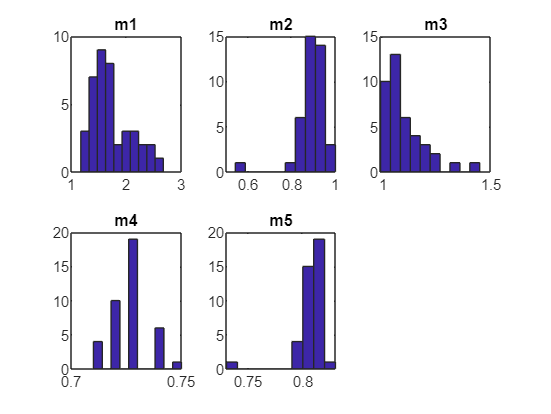

% histogram
histogram=figure;
title('histogram of t')
subplot(2,3,1)
hist(t1)
title('m1')

subplot(2,3,2)
hist(t2)
title('m2')

subplot(2,3,3)
hist(t3)
title('m3')

subplot(2,3,4)
hist(t4)
title('m4')

subplot(2,3,5)
hist(t5)
title('m5')

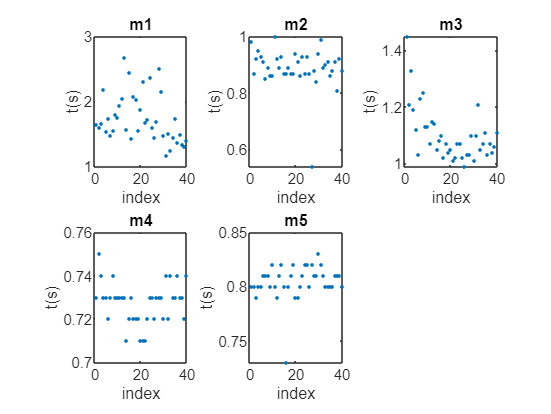


% scatter plot
scatter=figure;
subplot(2,3,1)
plot(1:40,t1,".")
title('m1')
ylabel('t(s)')
xlabel('index')

subplot(2,3,2)
plot(1:40,t2,".")
title('m2')
ylabel('t(s)')
xlabel('index')

subplot(2,3,3)
plot(1:40,t3,".")
title('m3')
ylabel('t(s)')
xlabel('index')

subplot(2,3,4)
plot(1:40,t4,".")
title('m4')
ylabel('t(s)')
xlabel('index')

subplot(2,3,5)
plot(1:40,t5,".")
title('m5')
ylabel('t(s)')
xlabel('index')

## calculating

% average time
tm1=mean(t1);
tm2=mean(t2);
tm3=mean(t3);
tm4=mean(t4);
tm5=mean(t5);

% creating array tm
tm=[tm1;tm2;tm3;tm4;tm5];

% space
s=s1-s2;

% height
h=h1-h2;

% angle
rteta=asin(h./s); %rad
dteta=(180./pi)*rteta; %deg

% test g
g1=(2.*s)/(sin(rteta).*((mean(t1)).^2))

g1 = 1.5268

g2=(2.*s)/(sin(rteta).*((mean(t2)).^2))

g2 = 5.8207

g3=(2.*s)/(sin(rteta).*((mean(t3)).^2))

g3 = 3.8014

g4=(2.*s)/(sin(rteta).*((mean(t4)).^2))

g4 = 8.7066

g5=(2.*s)/(sin(rteta).*((mean(t5)).^2))

g5 = 7.1197

% creating empty array
% acceleration
a=zeros(lm,1);
da=zeros(lm,1);
rea=zeros(lm,1); % relative error (acceleration)
%coefficient of friction
mu=zeros(lm,1);
dmu=zeros(lm,1);
rec=zeros(lm,1); % relative error (coefficient)
% first significant value position
cfra=zeros(lm,1);
cfr=zeros(lm,1);

% c'è qualcosa che non va nell'errore relativo dell'accelerazione?

for i=1:lm

    % calculating accelerations
    a(i)=(2.*s)/((tm(i)).^2);

    % calculating coefficient of friction
    mu(i)=tan(rteta)-(a(i)./g.*cos(rteta));
    
    % propagation of uncertainty acceleration
    da(i)=(2.*(ds+(4.*s.*dt)))./(tm(i).^2);
    
    % propagation of uncertainty coefficient
    dmu(i)=(((2.*ds)/(((cos(rteta)).^2)*sqrt(s.^2-h^2))).*(1-((a(i).*sin(rteta))./g)).*(1+(h./s)))+((2.*(ds+(4.*s.*dt)))./((tm(i).^2).*g.*cos(rteta)))+((a(i).*dg)./((g.^2).*cos(rteta)));
    
    % rounding values
    cfr(i)=-floor(log10(dmu(i)));
    dmu(i)=round(dmu(i),cfr(i));
    mu(i)=round(mu(i),cfr(i));
    cfra(i)=-floor(log10(da(i)));
    da(i)=round(da(i),cfra(i));
    a(i)=round(a(i),cfra(i));
    
    % relative error
    rea(i)=(da(i)/a(i))*100;
    rea(i)=round(rea(i),2);
    rec(i)=(dmu(i)./mu(i))*100;
    rec(i)=round(rec(i),2);
end

% significant digits

as=string(zeros(lm,1));     %acceleration significant digits (temp)
mus=string(zeros(lm,1));    %mu significant digits (temp)

for i=1:lm
    as(i)=sprintf(strcat('%.',num2str(cfra(i)),'f'),round(a(i),cfra(i)));
    mus(i)=sprintf(strcat('%.',num2str(cfr(i)),'f'),round(mu(i),cfr(i)));
end

% converting a,mu,rea,rec array to string
a=string(a);
mu=string(mu);
rea=string(rea);
rec=string(rec);

% substituting values
for i=1:lm
    a(i)=as(i);
    mu(i)=mus(i);
    rec(i)=sprintf('%.2f',rec(i));
    rea(i)=sprintf('%.2f',rea(i));
end

% creating output array
acceleration=string(horzcat(a,da,rea))

acceleration = 5×3 string array
    "0.85"    "0.03"    "3.53"
    "3.2"     "0.1"     "3.13"
    "2.11"    "0.09"    "4.27"
    "4.8"     "0.2"     "4.17"
    "4.0"     "0.2"     "5.00"


coefficient=string(horzcat(mu,dmu,rec))

coefficient = 5×3 string array
    "0.596"    "0.008"    "1.34" 
    "0.39"     "0.02"     "5.13" 
    "0.49"     "0.01"     "2.04" 
    "0.26"     "0.03"     "11.54"
    "0.33"     "0.02"     "6.06" 


% exporting csv
writetable(array2table(acceleration,'VariableNames',{'acceleration','uncertainty','relative_error'}),'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
writetable(array2table(coefficient,'VariableNames',{'coefficient_friction','uncertainty','relative_error'}),'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
saveas(histogram,'..\img\img-1.png');

saveas(scatter,'..\img\img-2.png');


% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);